# とりあえず吉村先生のmainLcUKFqを写経

### `photometric attitude estimation using UKF (quaternion)`

`yoshimuLibrary/examples/estimationLightCurve/mainLcUKFq.mlx`

### `state variables`


$${\bf x}=[{\bf q}^T, {\bf \omega}^T]^T$$


`q`: quaternion where q(4) is the scalar part 

`w`: angular rate, rad/s

### 使う関数(ざっくり)

- yoshimuLibrary/examples/lcUKF.mlx

clc
clear
close all
% cls

curdir = pwd;
addpath(genpath(strcat(curdir, '/../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../gpryui'));
% addpath(curdir);

### constants

earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

### simulation conditions

model = 3 % 1: symmetric flat plate, 2: asymmetric inertia flat plate

model = 3

observation = 'mag'; % light curve magnitude or its inverse value

% random number generator
rng(2022, 'twister');

### load true value and set noise

objName.mat = `['t_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'r', 'v', 'obsECI', 'jdHistory', 'sat', 'obsRel', 'sunPosI']` 

if model == 1
    load('flatPlate.mat');
elseif model == 2
    load('flatPlateAsym.mat');
elseif model == 3
    load('boxWing.mat');
end

tn_ = length(t_);
    % sat.nu = ones(length(sat.Cs), 1) .* 300;
    % sat.nv = ones(length(sat.Cs), 1) .* 300;

sigTrue = 0.1; % standard deviation of observation noise
Rtrue = sigTrue^2; % observation noise variance for relative magnitude

### UKF paras. わからん

n_ = 3; % # of state variable := [error GRP and angular rate]

% UKF Parameters
ukfPara.alp = 1e-4;
ukfPara.beta = 2;
ukfPara.kap = 3 - n_;
ukfPara.lam = ukfPara.alp^2 * (n_ + ukfPara.kap) - n_;
ukfPara.lam = 0; % わからん：上書きしてね

ukfPara.w0m = ukfPara.lam / (n_ + ukfPara.lam); % for mean
ukfPara.wim = 1 / (2 * (n_ + ukfPara.lam));
ukfPara.w0c = ukfPara.lam / (n_ + ukfPara.lam) + (1 - ukfPara.alp^2 + ukfPara.beta); % for covariance
ukfPara.wic = ukfPara.wim;

ukfPara.w0m + 2*3*ukfPara.wim

ans = 1

ukfPara.w0c + 2*3*ukfPara.wic

ans = 4.0000


% estimated obsevation noise (standard deviation)
if strcmp(observation, 'mag')
    sigEst = 3 * sigTrue;
    Rest = sigEst.^2; % measurement noise
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
else
    sigEst = 1e-8;
    Rest = sigEst.^2;
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
end

### pre-allocation

xEst = zeros(tn_, n_); % [euler angles, angular rates]
p = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal = zeros(tn_, 4);
ye0 = 0; % わからん
yez = zeros(2*n_, 1);
yeOut = zeros(tn_, 1);

% observations
mAppNoise = mApp + sigTrue .* randn(tn_, 1); % true obs. (relative magnitude)
dTmp = vecnorm(obsRel, 2, 2); % m, distance between sat and observer
mAppInv = magInv(mAppNoise(:, 1), dTmp); % true obs. (relative magnitude inverse)

### initial estimate

% initial estimate
qGlobal(1, :) = q(1, :); % true initial
% large initial error
iniErr = deg2rad(60);
% qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr, iniErr, iniErr), q(1,:));
% small initial error
qGlobal(1,:) = qMult(4, 1, zyx2q(4, deg2rad(20), deg2rad(-10), deg2rad(-10)), q(1,:));

#### initial covariance for 3$\sigma
$ bound

p(1, :) = (iniErr/3)^2 .* ones(1, 3);
Pcov = diag(p(1, :));

% x:= [eror GRP, angular rate]
xEst(1, :) = zeros(1, n_);

### Generalized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

## UKF

% modify optical paras.
% sat.F0 = 0.6;
% sat.nu = 800;
% sat.nv = 800;
% sat.Cd = 0.2;

for i = 1:tn_-1
    dt_ = t_(i+1) - t_(i);
    [qGlobal(i+1, :), Pcov] = lcUKF_h(jdHistory(i+1), dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), w(i,:), r(i+1,:), obsECI(i+1,:), sat, const, earthVSOP);
end

### data handling

qe = qErr(4, q, qGlobal);
zyxE = q2zyx(4, qe);
phiE = zyxE(:,1);
thetaE = zyxE(:,2);
psiE = zyxE(:,3);

### show figures

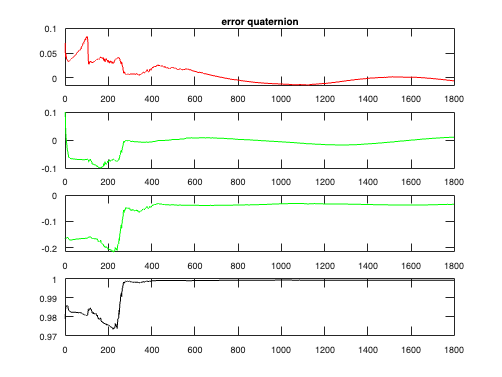

figure
tiledlayout(4, 1), nexttile
plot(t_, qe(:,1), 'r');
xlim([0 t_(end,1)])
title('error quaternion');

nexttile;
plot(t_, qe(:,2), 'g');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe(:, 3), 'g');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe(:, 4), 'k');
xlim([0 t_(end,1)])

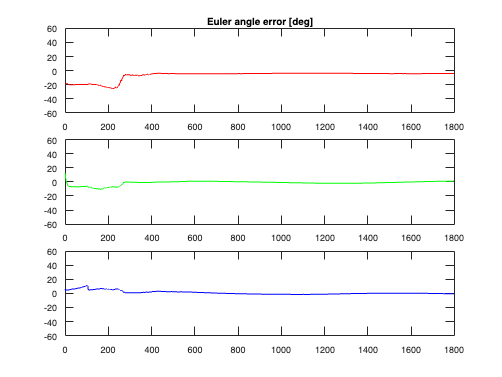


% figure
% tiledlayout(3,1), nexttile
% plot(t_/60, rad2deg(phiE), 'r'); % なんでt_/60をしてるの？
% title('Euler angle error [deg]');
% % xlim([0 60*6]), ylim([-60 60])
% xlim([0 t_(end,1)]), ylim([-60 60])
% nexttile
% plot(t_/60, rad2deg(thetaE), 'g');
% xlim([0 60*6]), ylim([-60, 60]);
% nexttile
% plot(t_/60, rad2deg(psiE), 'b');
% xlim([0 60*6]), ylim([-60 60]);
figure
tiledlayout(3,1), nexttile
plot(t_, rad2deg(phiE), 'r'); 
title('Euler angle error [deg]');
xlim([0 t_(end,1)]), ylim([-60 60])
nexttile
plot(t_, rad2deg(thetaE), 'g');
xlim([0 t_(end,1)]), ylim([-60, 60]);
nexttile
plot(t_, rad2deg(psiE), 'b');
xlim([0 t_(end,1)]), ylim([-60 60]);